# Polynomial design, cancelling of a process zero, incremental controller

Based on problem 5.3 from Åström & Wittenmark "Computer-controlled systems

We have a plant model $H(z) = \frac{z + 0.7}{z^2 - 1.8z + 0.81}$

and want to design a 2dof-controller

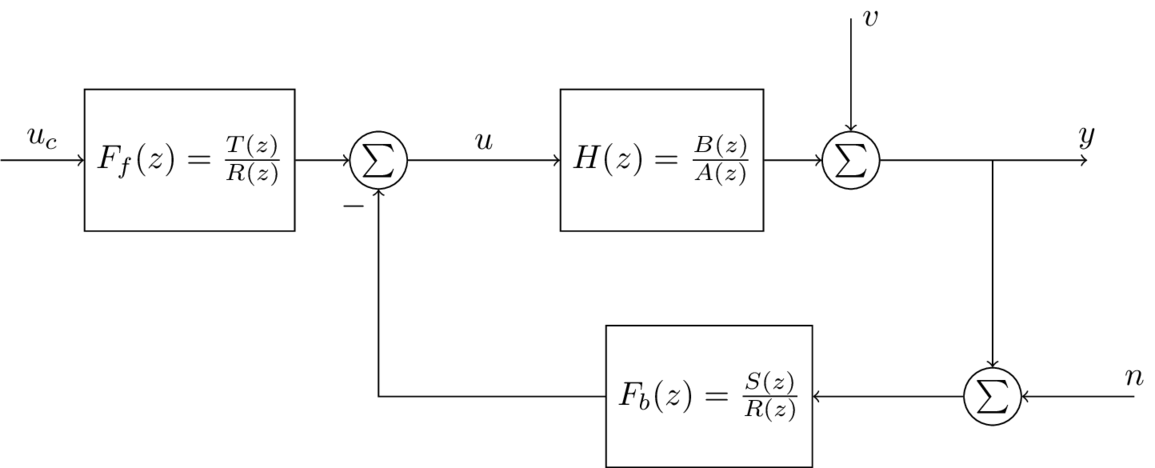

so that the closed-loop system from the command signal (set point) to the output has characteristic polynomial 


$$A_c(z) = z^2 - 1.5z + 0.6$$


set(0,'defaultlinelinewidth',2)

## The plant model

B = [1, 0.7];
A = [1, -1.8, 0.81];
H = tf(B, A, 1)

H =
 
       z + 0.7
  ------------------
  z^2 - 1.8 z + 0.81
 
Sample time: 1 seconds
Discrete-time transfer function.



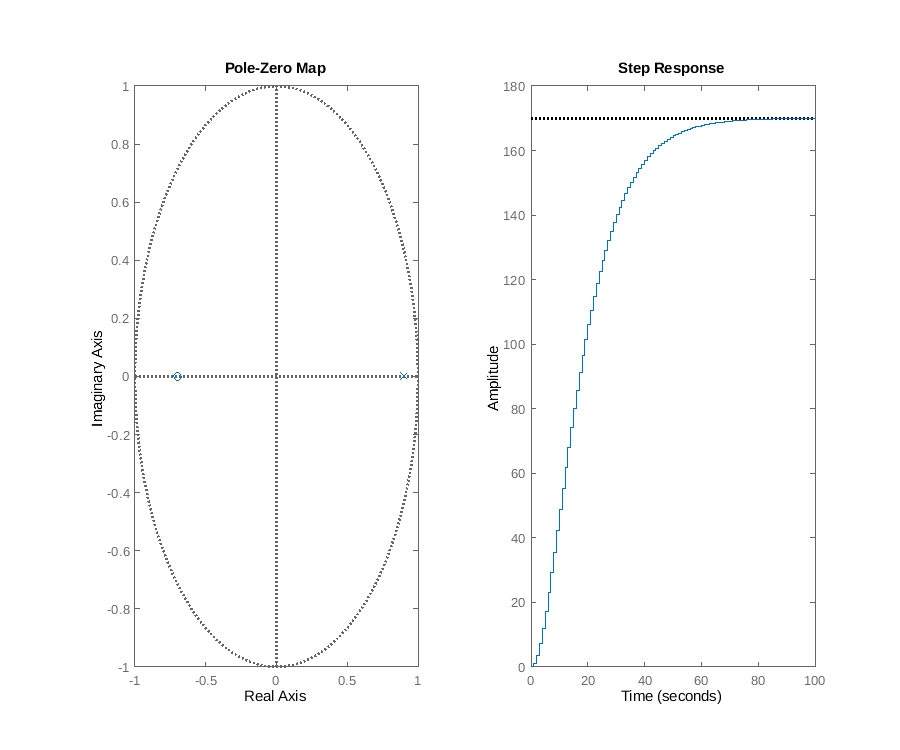


% For symbolic computations
syms z
As = poly2sym(A, z); % Generates polynomial A(1)*z^nA + A(2)*z^(nA-1) + ...
Bs = poly2sym(B, z);

% Check behaviour
figure()
clf
subplot(121)
pzmap(H)
subplot(122)
step(H)



% Desired characteristic polynomial
Ac = [1, -1.5, 0.6];
Acs = poly2sym(Ac, z);


## Solutions

## (a) With cancellation of the zero

In order to cancel the process zero, the controller must have a pole at the same location. This gives $R(z)=(z+0.7)\bar{R}(z)$, and we get the Diophantine equation 

$A(z)(z+0.7)\bar{R}(z) + (z+0.7)S(z) = A_{cl}(z)$.

 We see that since $(z+0.7)$ is a factor of the left-hand side, it  must also be a factor of the right-hand side characteristic polynomial. This gives $A(z)\bar{R}(z) + S(z) = \bar{A}_{cl}(z)$ where $A_{cl}(z) = (z+0.7) \bar{A}_{cl}(z)$.

The Diophantine equation will thus give $\deg(A) + \deg(\bar{R})$ linear equations, and the number of unknown parameters in the controller


$$F_b(z) = \frac{s_0z^{n+1} + s_1z^{n} + \cdots + s_{n+1}}{(z+0.7)(z^n + r_1z^{n-1} + \cdots + r_n)}$$


is $n+n+2=2\deg(\bar{R}) + 2$.

Setting the number of equations equal to the number of unknown parameters gives

$\deg{\bar{R}} = \deg{A} - 2 = 0$.

Hence, the controller is

$F_b(z) = \frac{s_0z + s_1}{z-0.7}$.

% Using symbolic computation

% Since B(z) is cancelled
Bsa = poly2sym([1], z);

% Controller polynomials
r = [1]

r = 1

Rbars = poly2sym(r, z);
s = sym('s', [1, 1]); % Vector starts with s1
s = cat(2, sym('s0'), s); % Now it starts with s0
Ss = poly2sym(s, z);
    
% Left hand side of Diophantine eqn
disp('Left hand side of Diophantine eqn')

Left hand side of Diophantine eqn


LHS = collect(As*Rbars + Bsa*Ss, z)

$$LHS = z^{2}+\left(s_{0}-\frac{9}{5}\right)\,z+s_{1}+\frac{81}{100}$$


% Right hand side
disp('Right hand side of Diophantine eqn')

Right hand side of Diophantine eqn


RHS = collect(Acs, z)

$$RHS = z^{2}-\frac{3\,z}{2}+\frac{3}{5}$$


% Coefficients
LHScoeffs = coeffs(LHS, z, 'All'); % Coefficients in increasing power of z
RHScoeffs = coeffs(RHS, z, 'All');

% Set up system of equations and solve
rr = [];
unknowns = cat(2, rr, s);
sol = solve(LHScoeffs(2:end) - RHScoeffs(2:end), unknowns); %

% Find t0 as Ac(1)/B(1)
t0 = subs(Acs, z, 1) / subs(Bsa, z, 1);

% Substitute numerical values

s0_n = double(sol.s0);
s1_n = double(sol.s1);

t0_n = double(t0);

R_c = [1,0.7];
S_c = [s0_n, s1_n]

S_c =     0.3000   -0.2100


T_c = t0_n*[1, 0]; % Add zero in the origin, so that T(z) and R(z) has same degree. 

% Define the controller
F_fb_a = tf(S_c, R_c, 1);
F_ff_a = tf(T_c, R_c, 1);

% Closed-loop system from command signal to output
Hc_a = minreal(F_ff_a * feedback(H, F_fb_a))

Hc_a =
 
        0.1 z
  -----------------
  z^2 - 1.5 z + 0.6
 
Sample time: 1 seconds
Discrete-time transfer function.



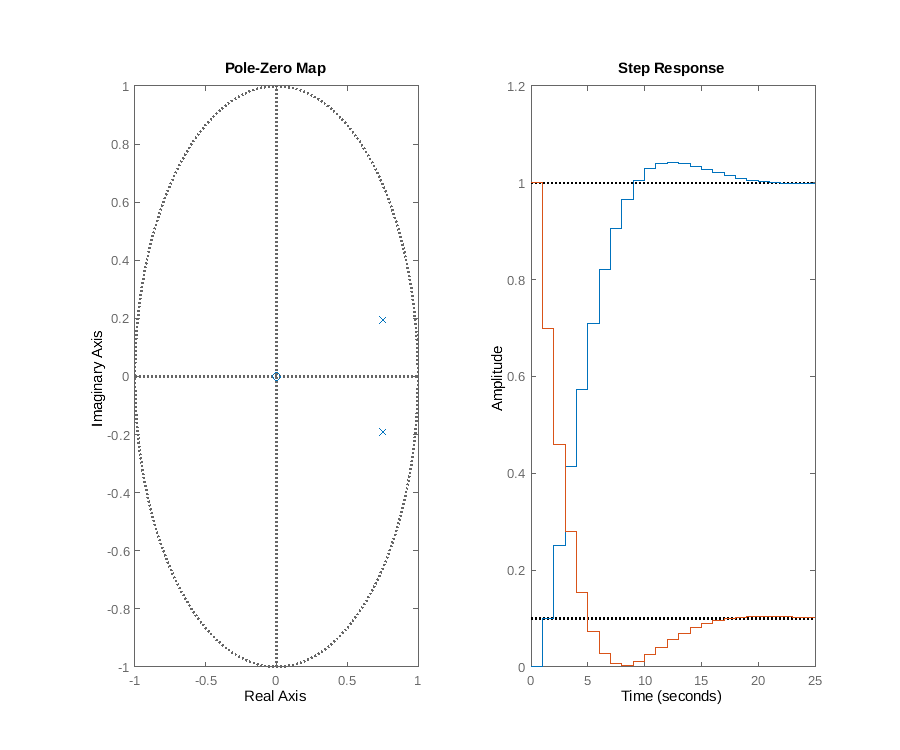


% Closed-loop system from command signal to control signal
Huc_a = minreal(F_ff_a * feedback(1, H*F_fb_a));

% Closed-loop system from disturbance signal to output
Hvc_a = minreal(feedback(1, H*F_fb_a));

% Plot response
figure()
clf
subplot(121)
pzmap(Hc_a)
subplot(122)
step(Hc_a, Hvc_a)

## (b) No cancellation of the zero

The Diophantine equation becomes

$A(z)R(z) + B(z)S(z) = A_{c}(z)A_o(z)  $.

 The Diophantine equation will give $\deg(A) + \deg(R)$ linear equations, and the number of unknown parameters in the controller


$$F_b(z) = \frac{s_0z^{n} + s_1z^{n-1} + \cdots + s_{n}}{z^n + r_1z^{n-1} + \cdots + r_n}$$


is $n+n+1=2\deg(R) + 1$.

Setting the number of equations equal to the number of unknown parameters gives

$\deg{R} = \deg{A} - 1 = 1$.

Hence, the controller is

$F_b(z) = \frac{s_0z + s_1}{z+r_1}$.

The LHS of the Diophantine equation is of degree 3. The desired closed-loop characteristic polynomial is $A_c(z) = z^2 - 1.5z + 0.6$ which is of degree 2. That means we have one observer pole to place. Place this in the origin for a deadbeat (fastest possible) observer.


%------------------------------------
% Solve using symbolic math toolbox!
%------------------------------------

% Controller polynomials
r = [1, sym('r1')];
s = sym('s', [1, 1]); % Vector starts with s1
s = cat(2, sym('s0'), s); % Now it starts with s0
Rs = poly2sym(r, z);
Ss = poly2sym(s, z);
    

% Left hand side of Diophantine eqn
disp('Left hand side of Diophantine eqn')

Left hand side of Diophantine eqn


LHS = collect(As*Rs + Bs*Ss, z)

$$LHS = z^{3}+\left(r_{1}+s_{0}-\frac{9}{5}\right)\,z^{2}+\left(\frac{7\,s_{0}}{10}-\frac{9\,r_{1}}{5}+s_{1}+\frac{81}{100}\right)\,z+\frac{81\,r_{1}}{100}+\frac{7\,s_{1}}{10}$$


% Right hand side
p0 = 0; % observer pole
Ao = poly2sym([1, -p0], z);
disp('Right hand side of Diophantine eqn')

Right hand side of Diophantine eqn


RHS = collect(Acs*Ao, z)

$$RHS = z^{3}-\frac{3\,z^{2}}{2}+\frac{3\,z}{5}$$


% Coefficients
LHScoeffs = coeffs(LHS, z, 'All'); % Coefficients in increasing power of z
RHScoeffs = coeffs(RHS, z, 'All');

% Set up system of equations and solve
unknowns = cat(2, r(2:end), s);
sol = solve(LHScoeffs(2:end) - RHScoeffs(2:end), unknowns); %

% Find t0 as Ac(1)/B(1)
t0 = subs(Acs, z, 1) / subs(Bs, z, 1);

% Substitute numerical values

s0_n = double(sol.s0);
s1_n = double(sol.s1);
r1_n = double(sol.r1);
t0_n = double(t0);

R_c = [1, r1_n];
S_c = [s0_n, s1_n]

S_c =     0.1852   -0.1329


T_c = t0_n*[1, 0]; % Add zero in the origin, so that T(z) and R(z) has same degree. 

% Define the controller
F_fb_b = tf(S_c, R_c, 1);
F_ff_b = tf(T_c, R_c, 1);

% Closed-loop system from command signal to output
Hc_b = F_ff_b * feedback(H, F_fb_b)

Hc_b =
 
   0.05882 z^3 + 0.04793 z^2 + 0.004729 z
  ----------------------------------------
  z^4 - 1.385 z^3 + 0.4277 z^2 + 0.06891 z
 
Sample time: 1 seconds
Discrete-time transfer function.



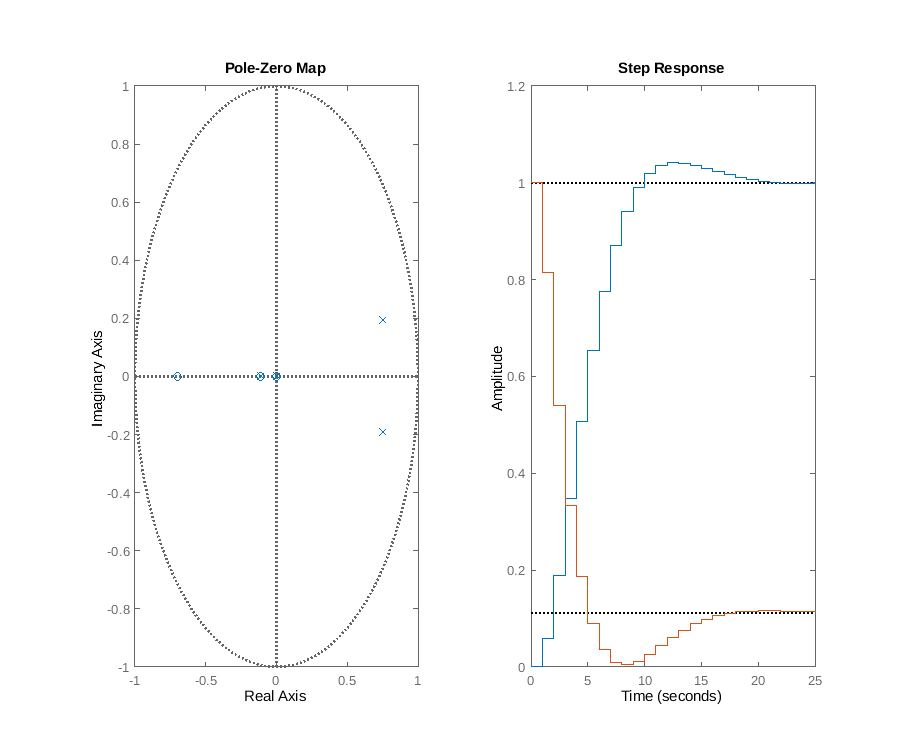


% Closed-loop system from command signal to control signal
Huc_b = F_ff_b * feedback(1, H*F_fb_b);

% Closed-loop system from disturbance signal to output
Hvc_b = feedback(1, H*F_fb_b);

% Plot response
figure()
clf
subplot(121)
pzmap(Hc_b)
subplot(122)
step(Hc_b, Hvc_b)

## Controller (c), incremental control

The Diophantine equation becomes

$A(z)(z-1)R(z) + B(z)S(z) = A_{c}(z)A_o(z)  $.

 The Diophantine equation will give $\deg(A) + \deg(R) + 1$ linear equations, and the number of unknown parameters in the controller


$$F_b(z) = \frac{s_0z^{n+1} + s_1z^{n} + \cdots + s_{n+1}}{(z-1)(z^n + r_1z^{n-1} + \cdots + r_n)}$$


is $n+n+2=2\deg R + 2$.

Setting the number of equations equal to the number of unknown parameters gives

$\deg{R} = \deg{A} +1-2 = \deg{A} - 1 = 1$.

Hence, the controller is

$F_b(z) = \frac{s_0z^2 + s_1z + 1}{(z-1)(z+r_1)}$.

The LHS of the Diophantine equation is of degree 4. The desired closed-loop characteristic polynomial is $A_c(z) = z^2 - 1.5z + 0.6$ which is of degree 2. That means we have two observer poles to place. Place this in the origin for a deadbeat (fastest possible) observer.

%------------------------------------
% Solve using symbolic math toolbox!
%------------------------------------

% Controller polynomials
r = [1, sym('r1')];
s = sym('s', [1, 2]); % Vector starts with s1
s = cat(2, sym('s0'), s); % Now it starts with s0
Rs = poly2sym(r, z);
Ss = poly2sym(s, z);
    

% Left hand side of Diophantine eqn
disp('Left hand side of Diophantine eqn')

Left hand side of Diophantine eqn


LHS = collect(As*(z-1)*Rs + Bs*Ss, z)

$$LHS = z^{4}+\left(r_{1}+s_{0}-\frac{14}{5}\right)\,z^{3}+\left(\frac{7\,s_{0}}{10}-\frac{14\,r_{1}}{5}+s_{1}+\frac{261}{100}\right)\,z^{2}+\left(\frac{261\,r_{1}}{100}+\frac{7\,s_{1}}{10}+s_{2}-\frac{81}{100}\right)\,z+\frac{7\,s_{2}}{10}-\frac{81\,r_{1}}{100}$$


% Right hand side
p0 = 0; % observer pole
Ao = poly2sym([1, -p0], z) * poly2sym([1, -p0], z);
disp('Right hand side of Diophantine eqn')

Right hand side of Diophantine eqn


RHS = collect(Acs*Ao, z)

$$RHS = z^{4}-\frac{3\,z^{3}}{2}+\frac{3\,z^{2}}{5}$$


% Coefficients
LHScoeffs = coeffs(LHS, z, 'All'); % Coefficients in increasing power of z
RHScoeffs = coeffs(RHS, z, 'All');

% Set up system of equations and solve
unknowns = cat(2, r(2:end), s);
sol = solve(LHScoeffs(2:end) - RHScoeffs(2:end), unknowns); %

% Find t0 as Ac(1)/B(1)
t0 = subs(Acs, z, 1) / subs(Bs, z, 1);

% Substitute numerical values

s0_n = double(sol.s0);
s1_n = double(sol.s1);
s2_n = double(sol.s2);
r1_n = double(sol.r1);
t0_n = double(t0);

R_c = conv([1, -1], [1, r1_n]);
S_c = [s0_n, s1_n, s2_n];
T_c = t0_n*double(coeffs(Ao, z, 'All')) 

T_c =     0.0588         0         0




% Define the controller
F_fb_c = tf(S_c, R_c, 1);
F_ff_c = tf(T_c, R_c, 1);

% Closed-loop system from command signal to output
Hc_c = minreal(F_ff_c * feedback(H, F_fb_c))

Hc_c =
 
  0.05882 z + 0.04118
  -------------------
   z^2 - 1.5 z + 0.6
 
Sample time: 1 seconds
Discrete-time transfer function.



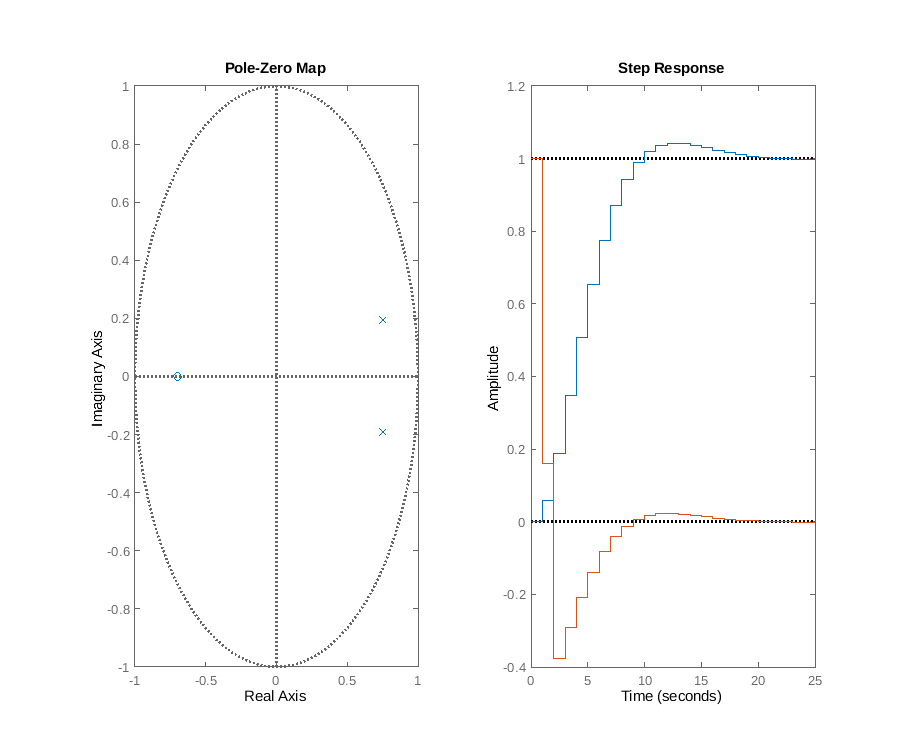


% Closed-loop system from command signal to control signal
Huc_c = minreal(F_ff_c * feedback(1, H*F_fb_c));

% Closed-loop system from disturbance signal to output
Hvc_c = minreal(feedback(1, H*F_fb_c));

% Plot response
figure()
clf
subplot(121)
pzmap(Hc_c)
subplot(122)
step(Hc_c, Hvc_c)

## Compare

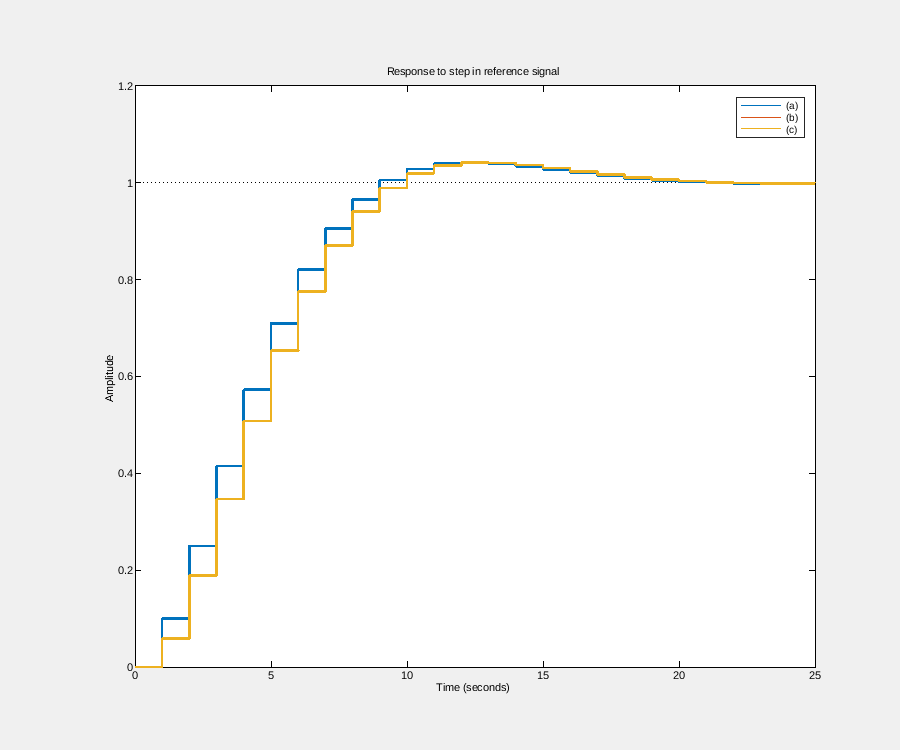

p = timeoptions;
p.XLabel.String = 'Time';

set(groot, 'Default', struct())

figure()
clf
step(Hc_a, Hc_b, Hc_c, p);
title('Response to step in reference signal');
legend('(a)', '(b)', '(c)');
h = findobj(gca,'Type','line');
set(h, 'linewidth', 2);

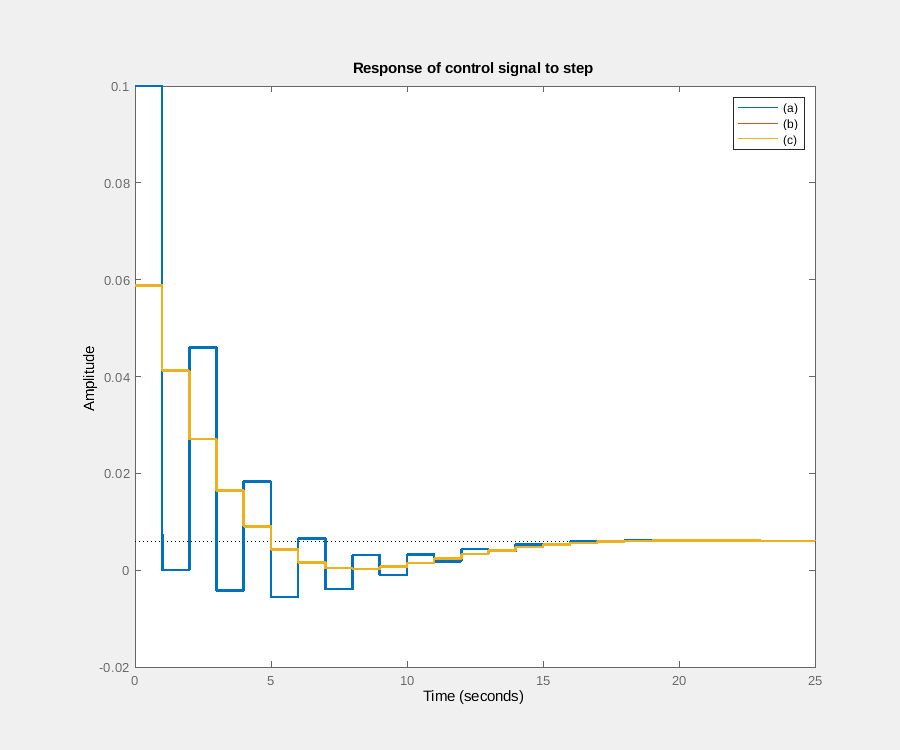

xlabel('Time');
%print -dpdf aw5_3_refstep.pdf


figure()
clf
step(Huc_a, Huc_b, Huc_c)
title('Response of control signal to step')
h = findobj(gca,'Type','line');
set(h, 'linewidth', 2)
legend('(a)', '(b)', '(c)')

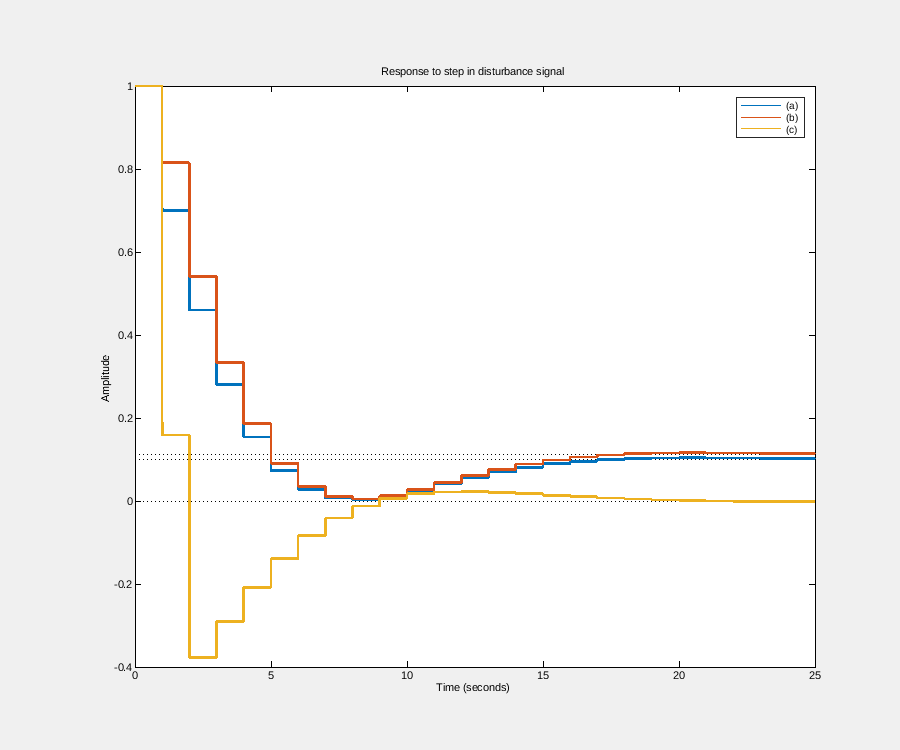


figure()
clf
h=stepplot(Hvc_a, Hvc_b, Hvc_c, p);
title('Response to step in disturbance signal')
legend('(a)', '(b)', '(c)')
h = findobj(gca,'Type','line');
set(h, 'linewidth', 2);

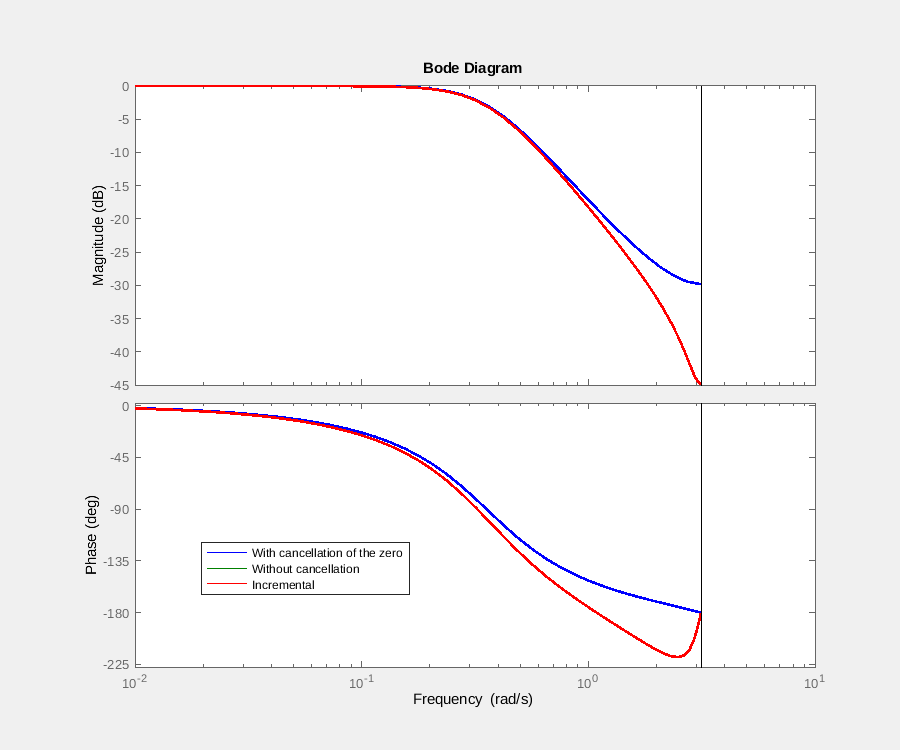

%print -dpdf aw5_3_diststep.pdf

figure()
clf
co_orig = get(groot, 'defaultAxesColorOrder');
co = [0 0 1;
      0 0.5 0;
      1 0 0;
      0 0.75 0.75;
      0.75 0 0.75;
      0.75 0.75 0;
      0.25 0.25 0.25];
set(groot,'defaultAxesColorOrder',co)
bode(Hc_a, Hc_b, Hc_c)
legend('With cancellation of the zero', 'Without cancellation', 'Incremental', ...
        'Location', 'best')
h = findobj(gcf,'Type','line');
set(h, 'linewidth', 2)
print -dpdf aw5_3_bode.pdf

set(groot,'defaultAxesColorOrder',co_orig)


